In the name of allah

# Linear Control Systems

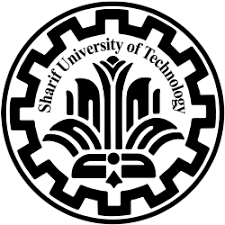

Hw 04

ali sadeghian 400101464

Fall 1402

# Theory Assignments

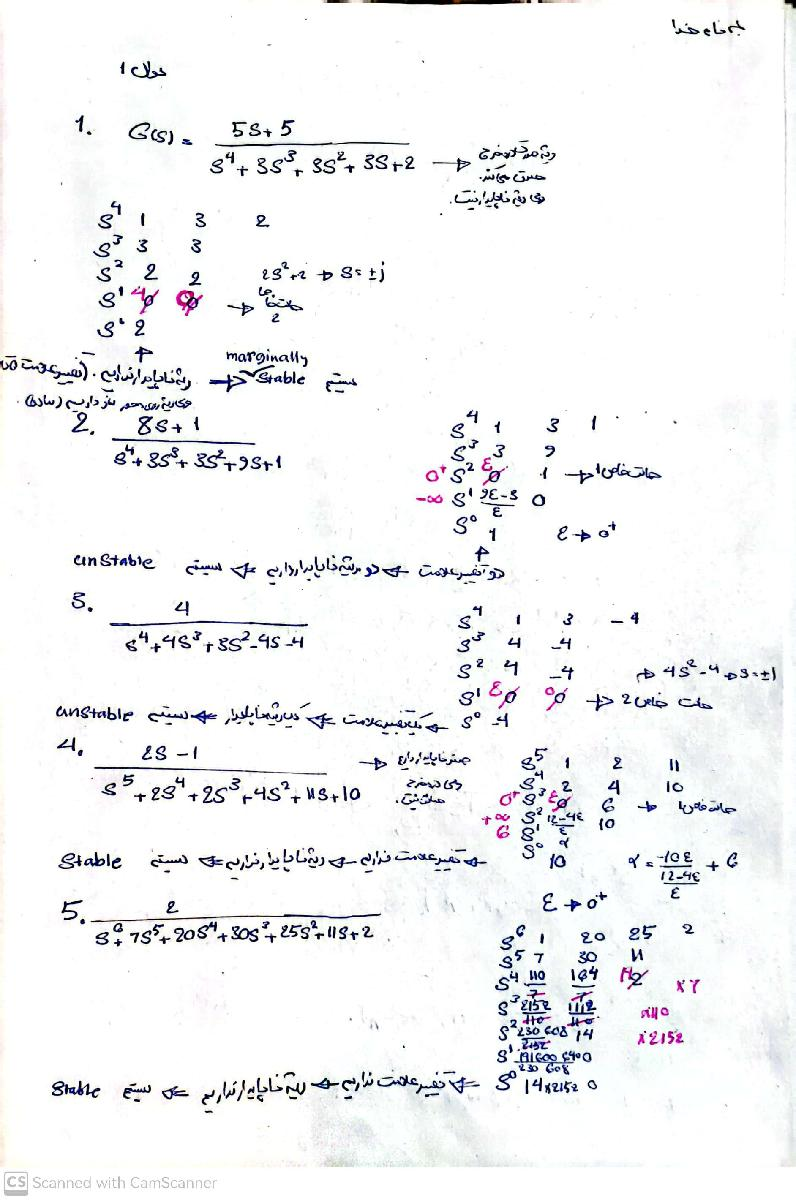

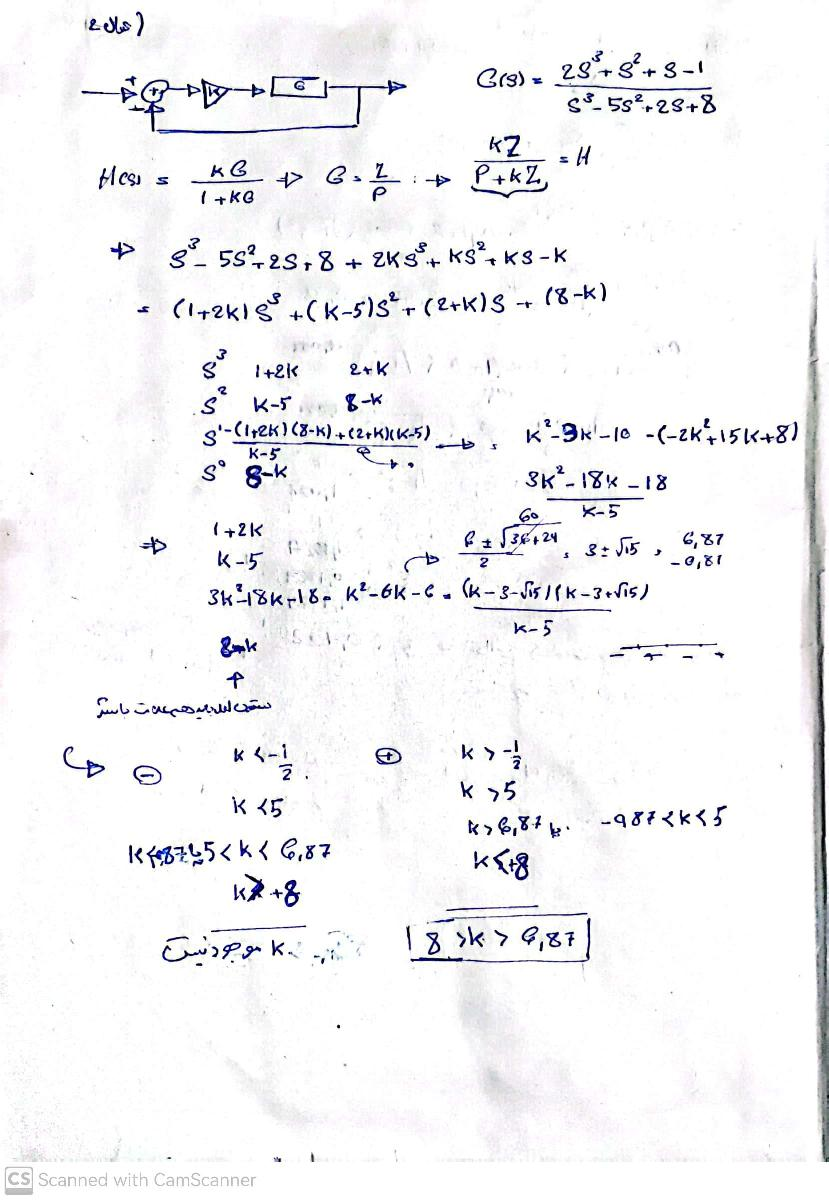

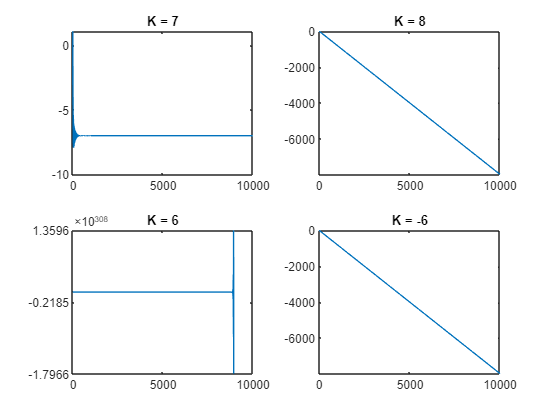

t = 0:0.01:10000;
u =  Step01(t);

K = 7;
num = [2*K K K -K];
den = [ 2*K+1 K-5 K+2 8-K];
sys = tf(num, den);
y1 = lsim(sys, u, t);

K = 8;
num = [2*K K K -K];
den = [ 2*K+1 K-5 K+2 8-K];
sys = tf(num, den);
y2 = lsim(sys, u, t);

K = 6;
num = [2*K K K -K];
den = [ 2*K+1 K-5 K+2 8-K];
sys = tf(num, den);
y3 = lsim(sys, u, t);

K = -6;
num = [2*K K K -K];
den = [ 2*K+1 K-5 K+2 8-K];
sys = tf(num, den);
y4 = lsim(sys, u, t);


figure
subplot(2,2,1)
plot(t,y1)
title("K = 7")
xlim([0 10000])
subplot(2,2,2)
plot(t,y2)
title("K = 8")
xlim([0 10000])
subplot(2,2,3)
plot(t,y3)
title("K = 6")
xlim([0 10000])
subplot(2,2,4)
plot(t,y2)
title("K = -6")
xlim([0 10000])

As we see, for $6\ldotp 87<K<8$ system is stable

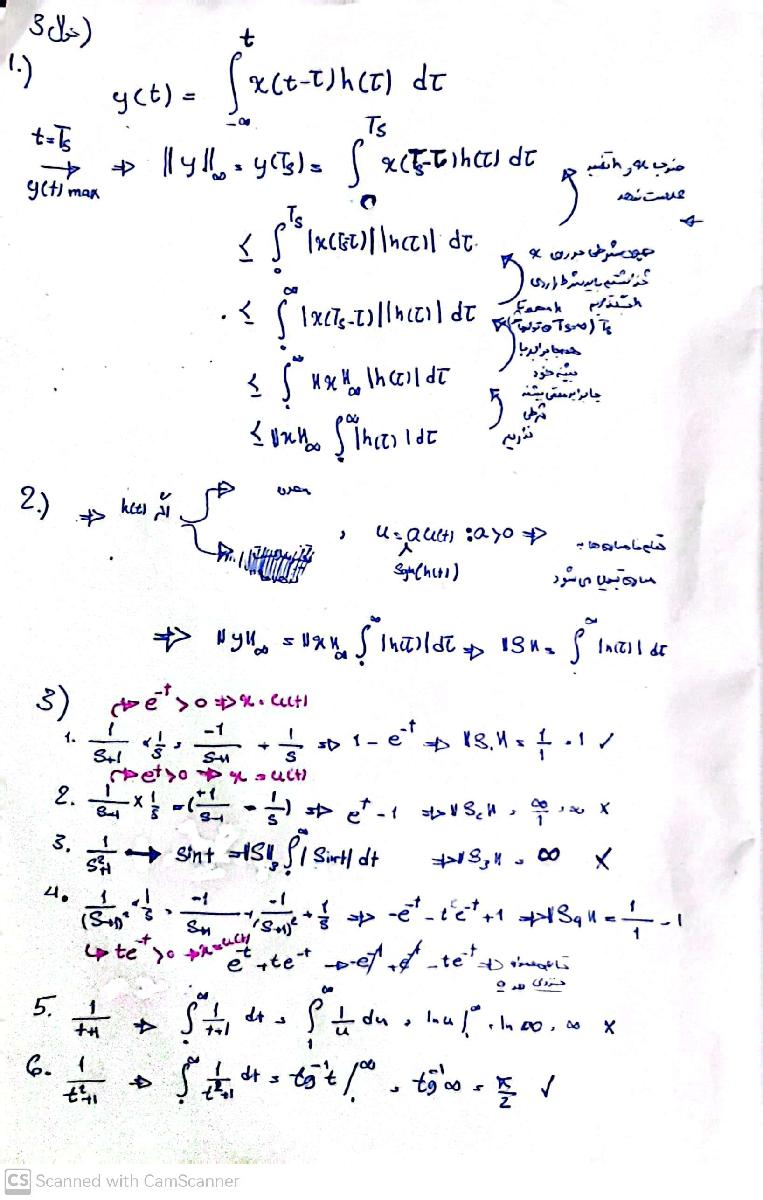

t = 0:0.01:100;
u =  Step01(t);

num = [1] ;
den = [1 1];
sys = tf(num, den);
y1 = lsim(sys, u, t);

num = [1] ;
den = [1 -1];
sys = tf(num, den);
y2 = lsim(sys, u, t);

num = [1] ;
den = [1 0 1];
sys = tf(num, den);
y3 = lsim(sys, u, t);

num = [1] ;
den = [1  2 1];
sys = tf(num, den);
y4 = lsim(sys, u, t);

syms e
y5 = (-1/(e+1)^2); % s(t) = d/dt h(t)

$$y5 = -\frac{1}{{\left(e+1\right)}^{2}}$$


y6 = (-2*e/(e^2+1)^2); % s(t) = d/dt h(t)

$$y6 = -\frac{2\,e}{{\left(e^{2}+1\right)}^{2}}$$

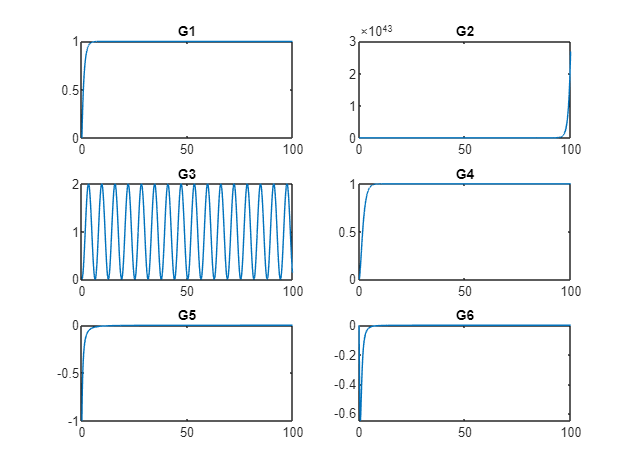


figure
subplot(3,2,1)
plot(t,y1)
title("G1")
xlim([0 100])
subplot(3,2,2)
plot(t,y2)
title("G2")
xlim([0 100])
subplot(3,2,3)
plot(t,y3)
title("G3")
xlim([0 100])
subplot(3,2,4)
plot(t,y4)
title("G4")
xlim([0 100])
subplot(3,2,5)
fplot(y5)
title("G5")
xlim([0 100])
subplot(3,2,6)
fplot(y6)
title("G6")
xlim([0 100])

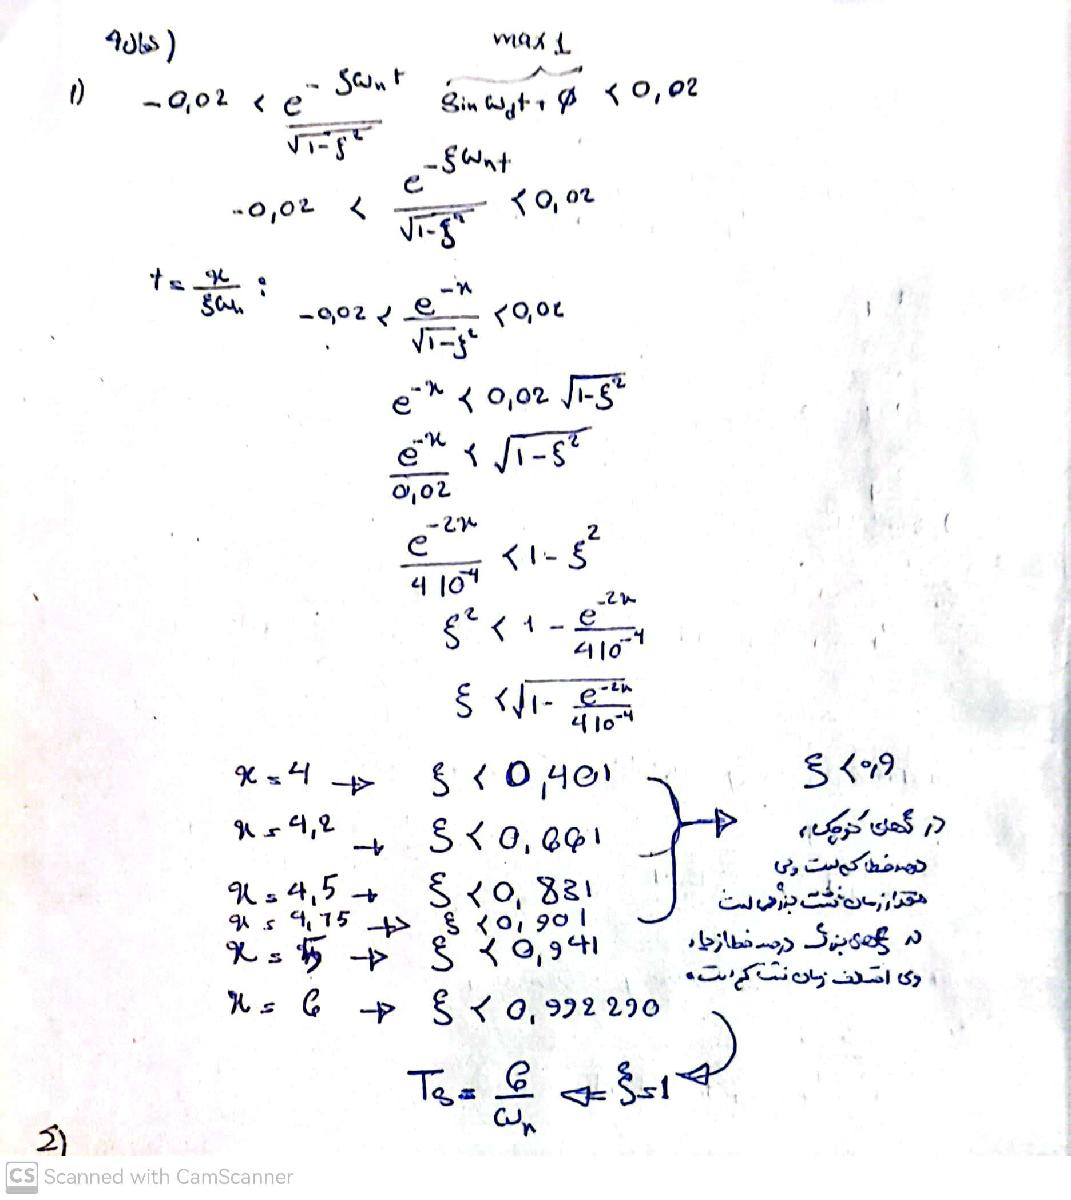

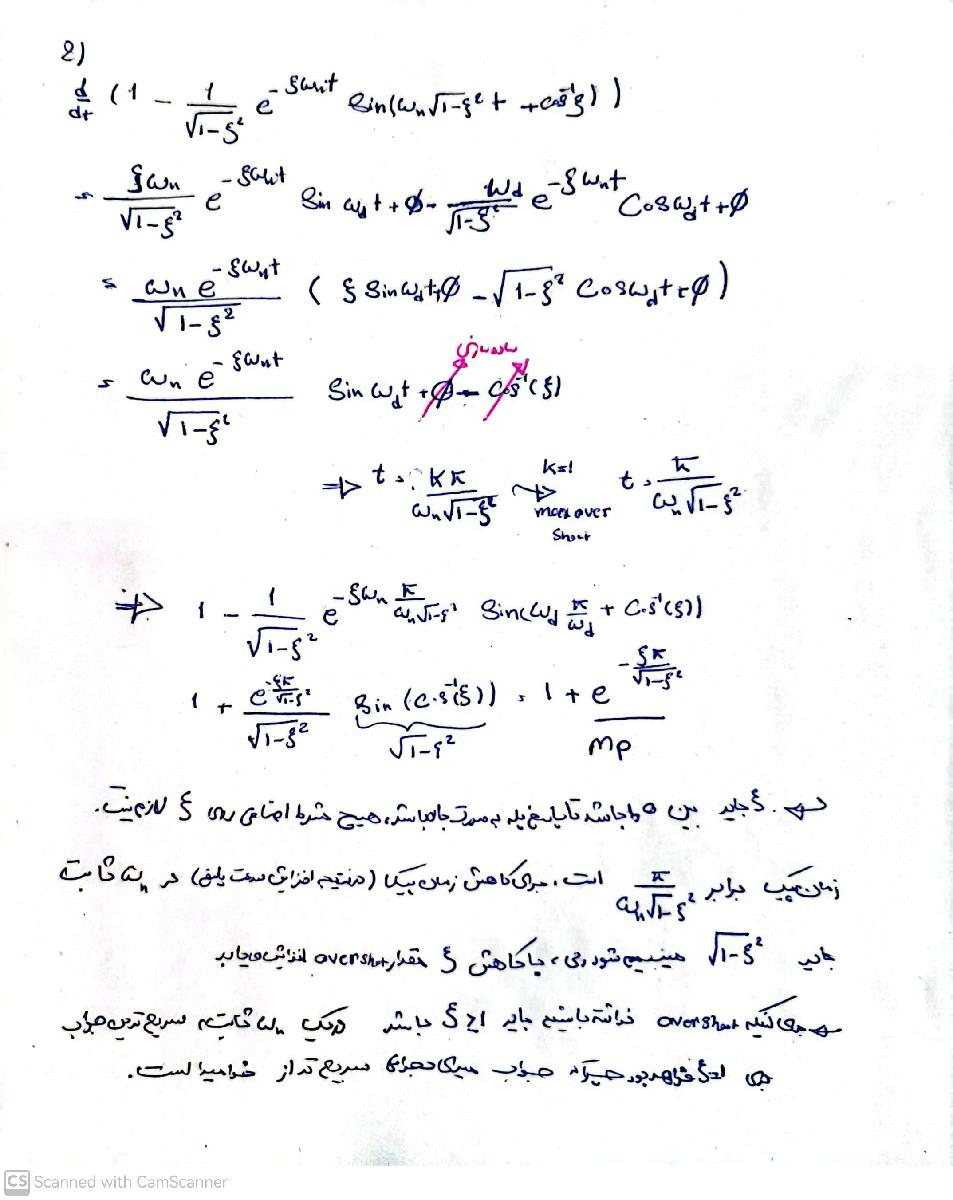

# MATLAB Assignments

clc
close all
clear all

# 5 Curve Fitting Toolbox

a)


$$\begin{array}{l}
G\left(s\right)=\frac{K}{\tau s+1}\Rightarrow \textrm{step}\;\textrm{response}:\;\frac{K}{\tau s+1}*\frac{1}{s}=\frac{-\frac{K}{\tau }}{\tau s+1}+\frac{K}{s}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;=\textrm{Ku}\left(t\right)-\frac{K}{\tau }e^{-\frac{t}{\tau }} 
\end{array}$$


b)

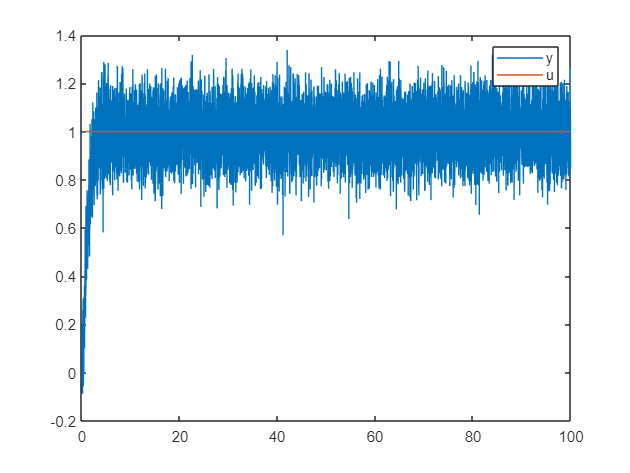

t = out.tout;
x = out.x;
y = out.y;

figure
plot(t,y,t,x) 
legend("y","u")

c)

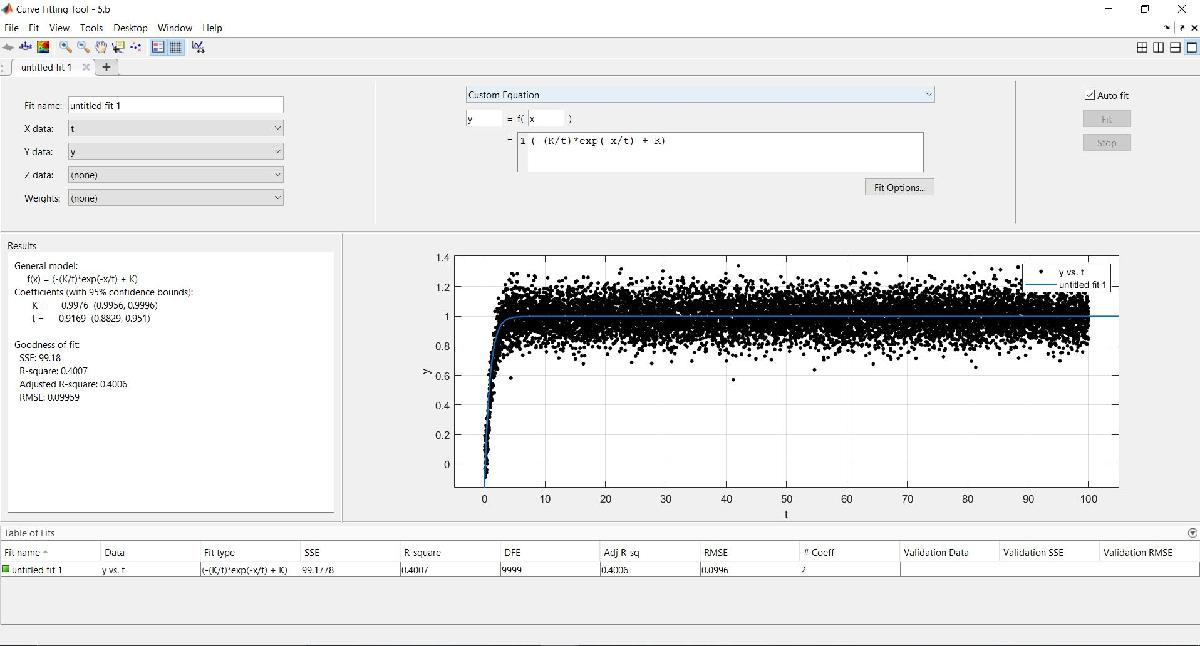

K = 0.9976 ,$\tau$ = 0.9169

d)

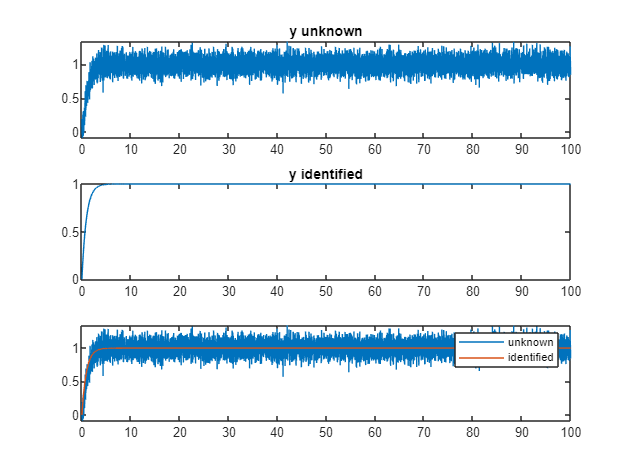

K = 0.9976;
T = 0.9169;
u =  Step01(t);

num = [K] ;
den = [T 1];
sys = tf(num, den);
y1 = lsim(sys, u, t);

figure
subplot(3,1,1)
plot(t,y)
title("y unknown")
subplot(3,1,2)
plot(t,y1)
title("y identified")
subplot(3,1,3)
plot(t,y,t,y1)
legend("unknown","identified")

e)


$$y\left(t\right)\;=\;\textrm{Ku}\left(t\right)-\frac{K}{\tau }e^{-\frac{t}{\tau }}$$


as we see, K  is almost equal to 1.

Also, in A = B, the output reaches its final value of 0.95.


$$y\left(4\right)\;=\;1-\frac{1}{\tau }e^{-\frac{4}{\tau }} =0\ldotp 95$$


K = 1 

$\tau$ = 1.573

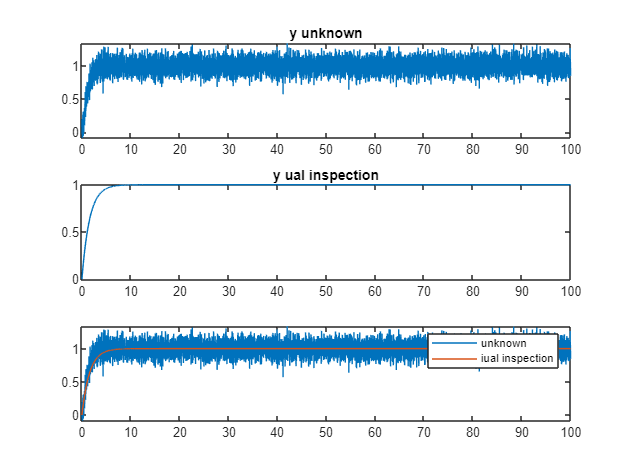

K = 1;
T = 1.573;
u =  Step01(t);

num = [K] ;
den = [T 1];
sys = tf(num, den);
y2 = lsim(sys, u, t);

figure
subplot(3,1,1)
plot(t,y)
title("y unknown")
subplot(3,1,2)
plot(t,y2)
title("y ual inspection")
subplot(3,1,3)
plot(t,y,t,y2)
legend("unknown","iual inspection")

f)

 
$$y\left(t\right)\;=\;\textrm{AKu}\left(t\right)-\frac{\textrm{AK}}{\tau }e^{-\frac{t}{\tau }} ,u\left(t\right)=\textrm{Au}\left(t\right)\;,A=3$$


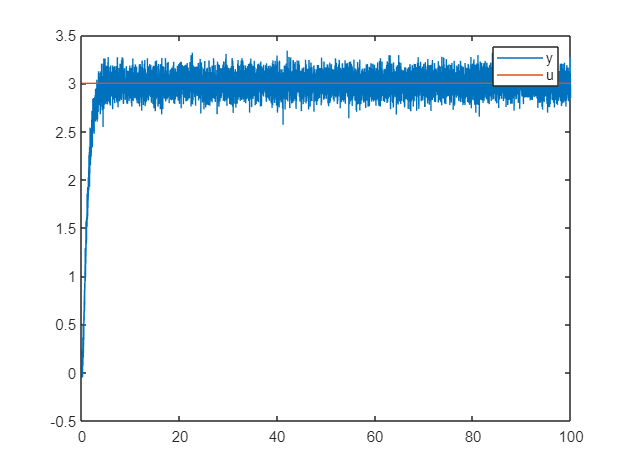

t = out.tout;
x = out.x;
y = out.y;

figure
plot(t,y,t,x) 
legend("y","u")

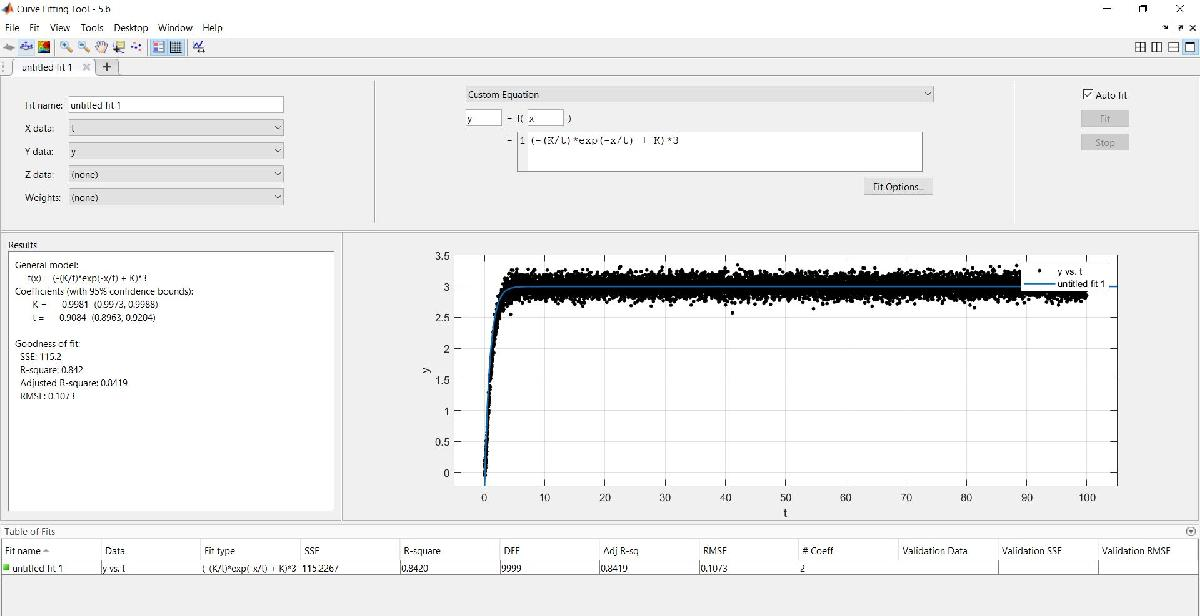

K = 0.9981 ,$\tau$ = 0.9084

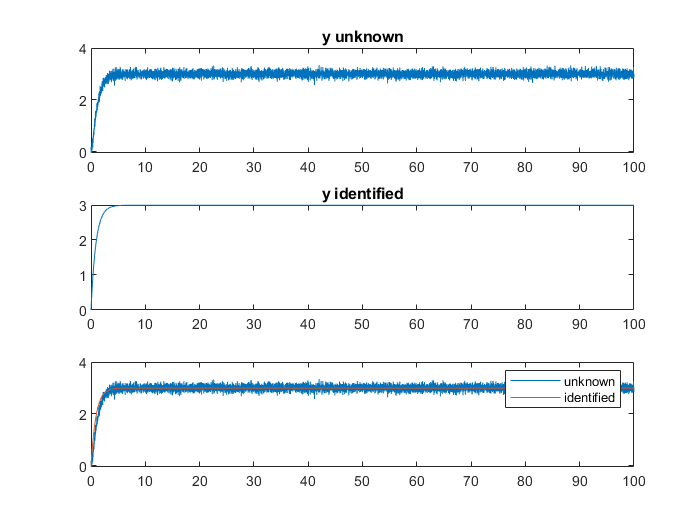

K = 0.9981;
T = 0.9084;
u =  Step01(t);

num = [K] ;
den = [T 1];
sys = tf(num, den);
y1 = lsim(sys, 3*u, t);

figure
subplot(3,1,1)
plot(t,y)
title("y unknown")
subplot(3,1,2)
plot(t,y1)
title("y identified")
subplot(3,1,3)
plot(t,y,t,y1)
legend("unknown","identified")

g)

sinusoidal respons

     
$$\begin{array}{l}
\;\frac{K}{\tau s+1}\ldotp \frac{a}{s^2 +a^2 }=\;\frac{\frac{{K\tau^2 a} }{1+\tau^2 a}}{\tau s+1}+\frac{-\frac{a\tau^2 K}{1+\tau^2 a }s+\frac{a \tau K}{1+\tau^2 a }}{s^2 +a^2 }\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \frac{{K\tau^2 a} }{1+\tau^2 a^2 }\;e^{-\frac{t}{\tau }} \;-\frac{a \tau^2 K}{1+\tau^2 a^2 }\cos \left(\textrm{at}\right)+\frac{\tau K}{1+\tau^2 a^2 }\sin \left(\textrm{at}\right)\\
a=1\Rightarrow \;\frac{{K\tau^2 } }{1+\tau^2 }\;e^{-\frac{t}{\tau }} \;-\frac{\tau^2 K}{1+\tau^2 }\cos \left(t\right)+\frac{\tau K}{1+\tau^2 }\sin \left(t\right)
\end{array}$$


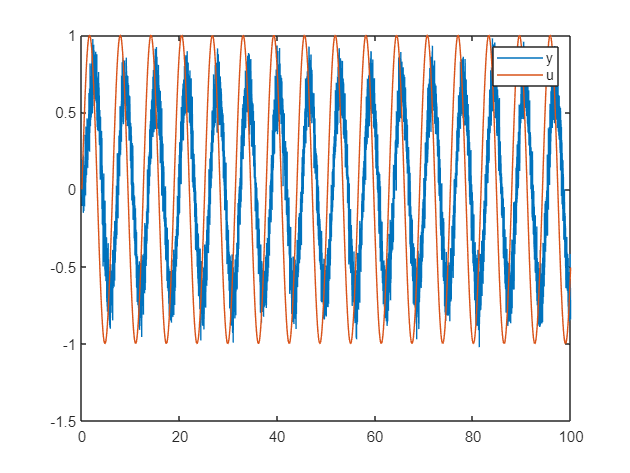

t = out.tout;
x = out.x;
y = out.y;

figure
plot(t,y,t,x) 
legend("y","u")

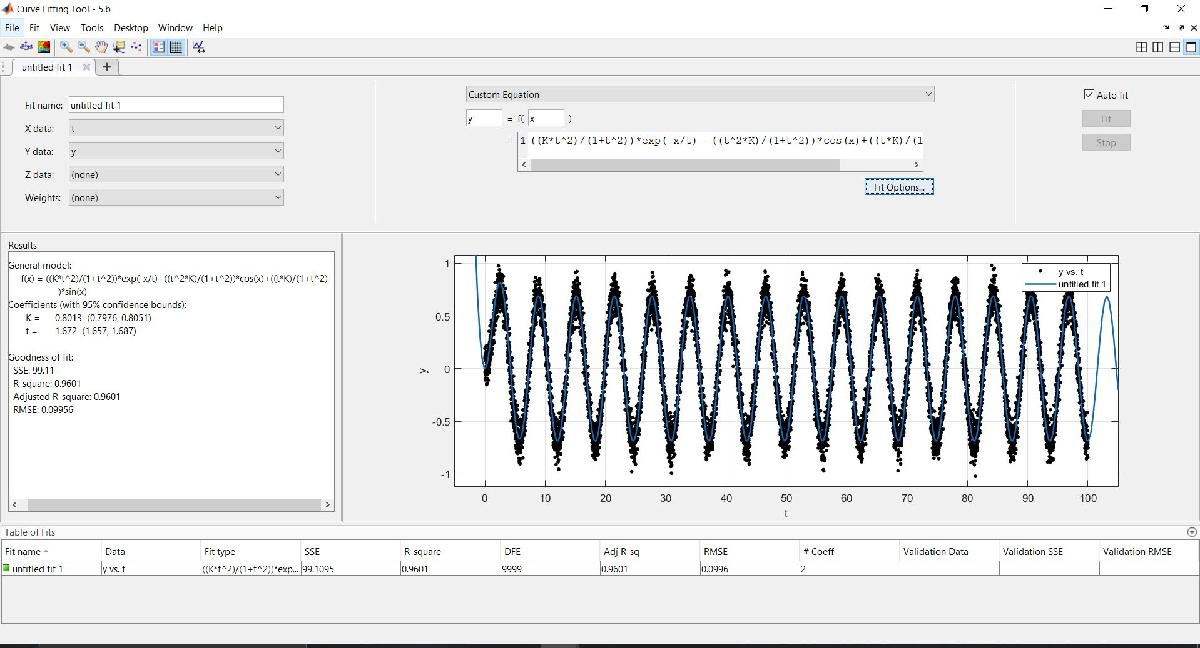

K = 0.8013 ,$\tau$ = 1.672

step respons

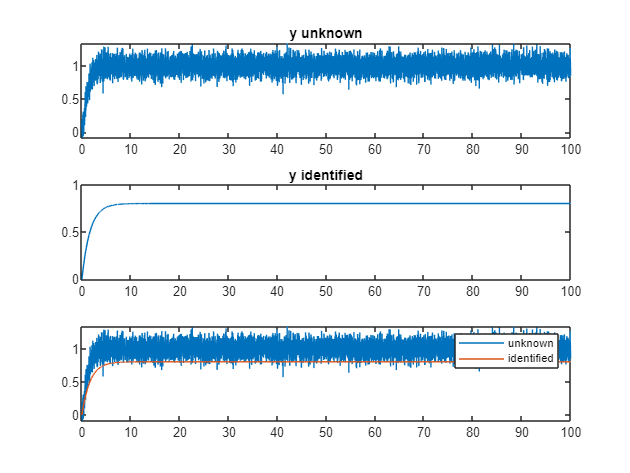

t = out.tout;
x = out.x;
y = out.y;

K = 0.8013;
T = 1.672;
u =  Step01(t);

num = [K] ;
den = [T 1];
sys = tf(num, den);
y1 = lsim(sys, u, t);

figure
subplot(3,1,1)
plot(t,y)
title("y unknown")
subplot(3,1,2)
plot(t,y1)
title("y identified")
subplot(3,1,3)
plot(t,y,t,y1)
legend("unknown","identified")

h)

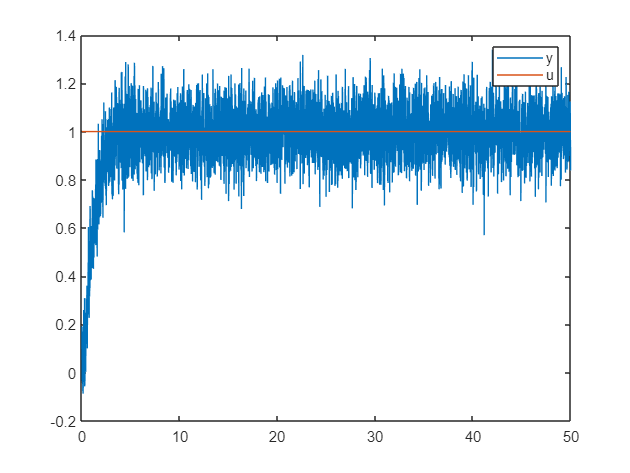

t = out.tout;
x = out.x;
y = out.y;

figure
plot(t,y,t,x) 
legend("y","u")

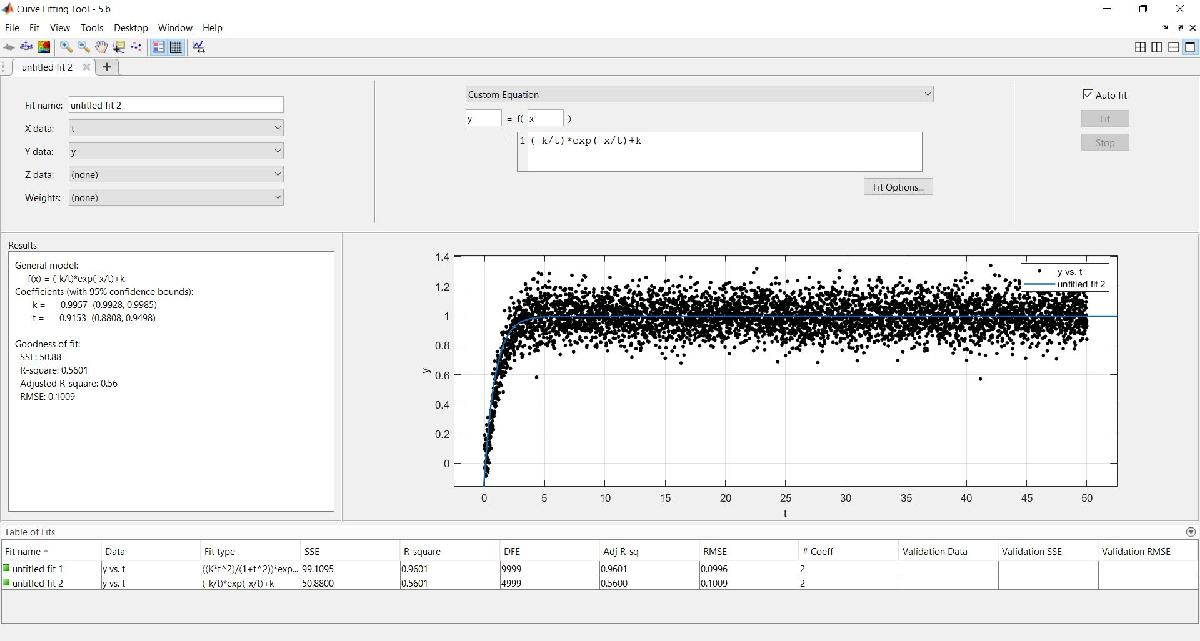

K = 0.9957 ,$\tau$ = 0.9153

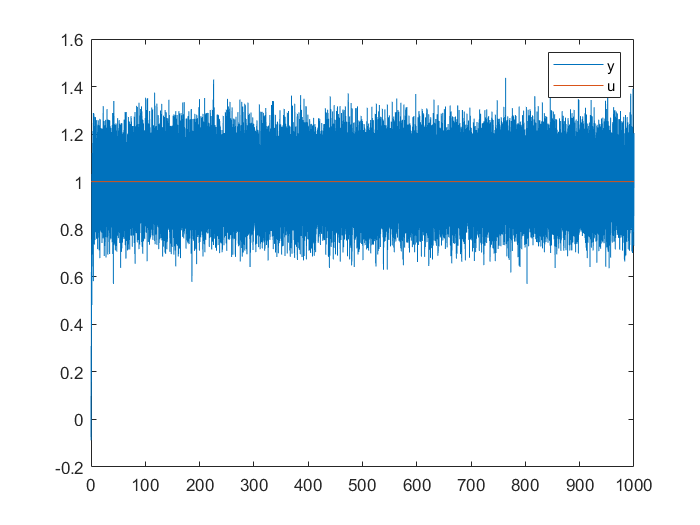

t = out.tout;
x = out.x;
y = out.y;

figure
plot(t,y,t,x) 
legend("y","u")

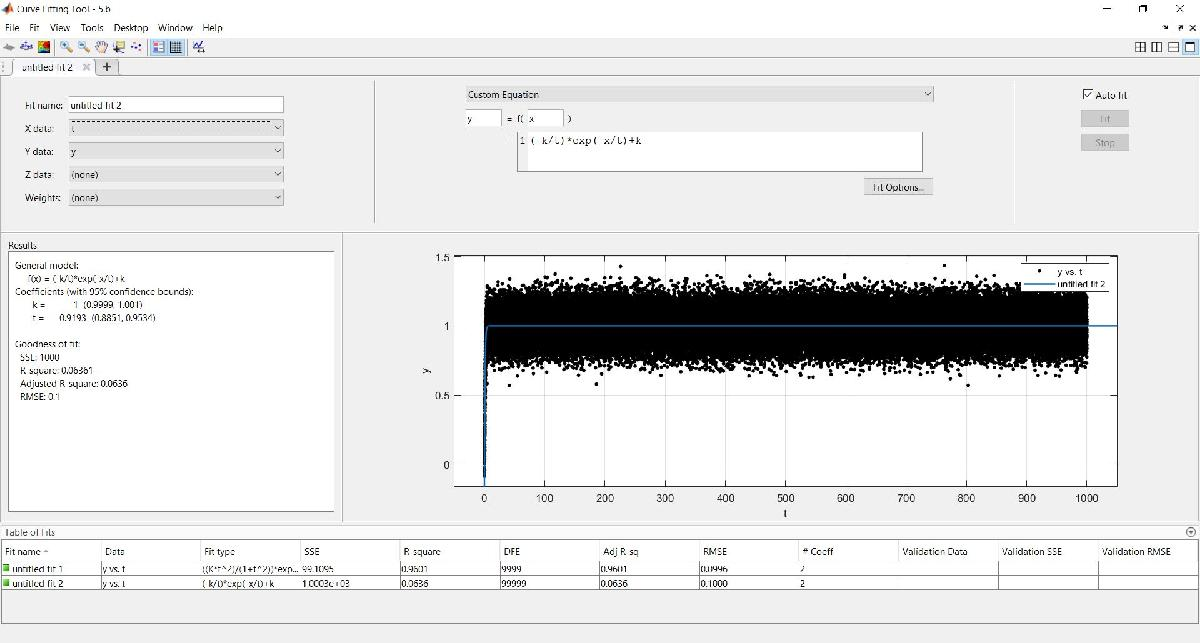

K = 1 ,$\tau$ = 0.9193

j)

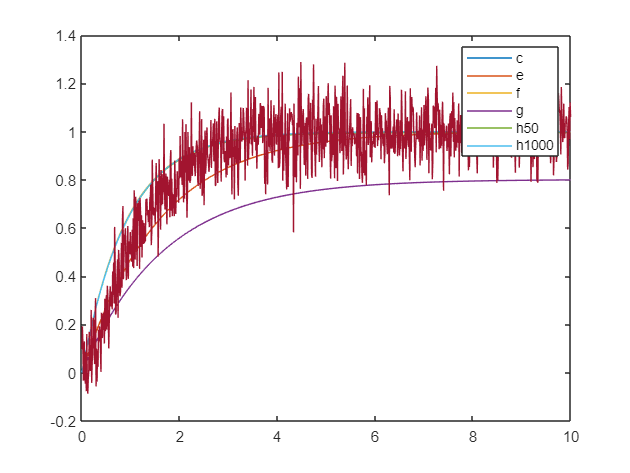

u =  Step01(t);


K = 0.9976;
T = 0.9169;
num = [K] ;
den = [T 1];
sys = tf(num, den);
y1 = lsim(sys, u, t);

K = 1;
T = 1.573;
num = [K] ;
den = [T 1];
sys = tf(num, den);
y2 = lsim(sys, u, t);

K = 0.9981;
T = 0.9084;
num = [K] ;
den = [T 1];
sys = tf(num, den);
y3 = lsim(sys, u, t);

K = 0.8013;
T = 1.672;
num = [K] ;
den = [T 1];
sys = tf(num, den);
y4 = lsim(sys, u, t);

K = 0.9957;
T = 0.9153;
num = [K] ;
den = [T 1];
sys = tf(num, den);
y5 = lsim(sys, u, t);

K = 1;
T = 0.9193;
num = [K] ;
den = [T 1];
sys = tf(num, den);
y6 = lsim(sys, u, t);

figure
plot(t,y1,t,y2,t,y3,t,y4,t,y5,t,y6,t,y) 
legend("c","e","f","g","h50","h1000")
xlim([0 10])

as we see,c,f,h50 &h1000 are good approximation.

Bonus

i)                                 

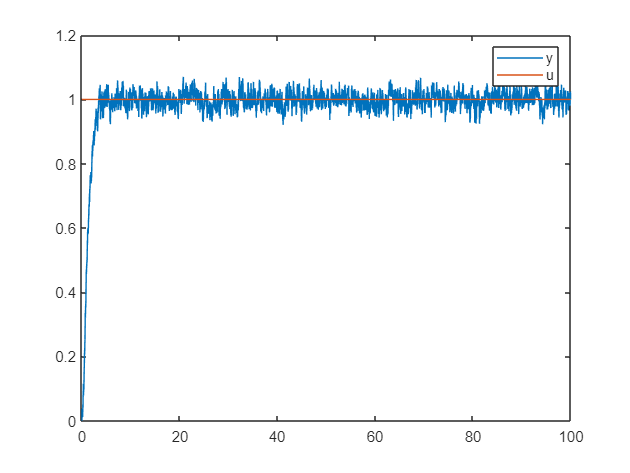

% t5 = out.tout;
% x5 = out.x;
% y5 = out.y;

figure
plot(t5,y5,t5,x5) 
legend("y","u")

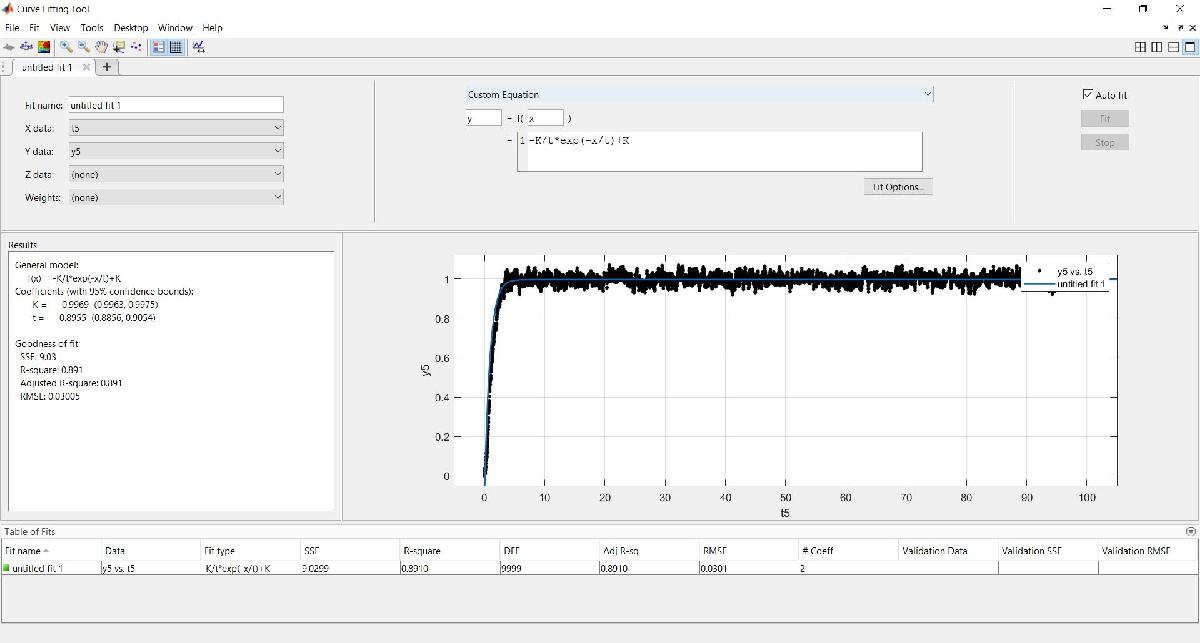

K = 0.9969 ,$\tau$ = 0.8955

k)


$$\begin{array}{l}
G\left(s\right)=\frac{K}{\left(\tau_1 s+1\right)\left(\tau_2 s+1\right)}\Rightarrow \textrm{step}\;\textrm{response}:\frac{K}{\left(\tau_1 s+1\right)\left(\tau_2 s+1\right)}*\frac{1}{s}=-\frac{\frac{K\tau_1 }{1-\frac{\tau_2 }{\tau_1 }}}{\tau_1 s+1}-\frac{\frac{K\tau_2 }{1-\frac{\tau_1 }{\tau_2 }}}{\tau_2 s+1}+\frac{K}{s}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \;=\textrm{Ku}\left(t\right)-\frac{K\tau_1 }{\tau_1 -\tau_2 }e^{-\frac{t}{\tau_1 }} -\frac{K\tau_2 }{\tau_2 -\tau_1 }e^{-\frac{t}{\tau_2 }} 
\end{array}$$


figure
plot(t5,y5,t5,x5) 
legend("y","u")

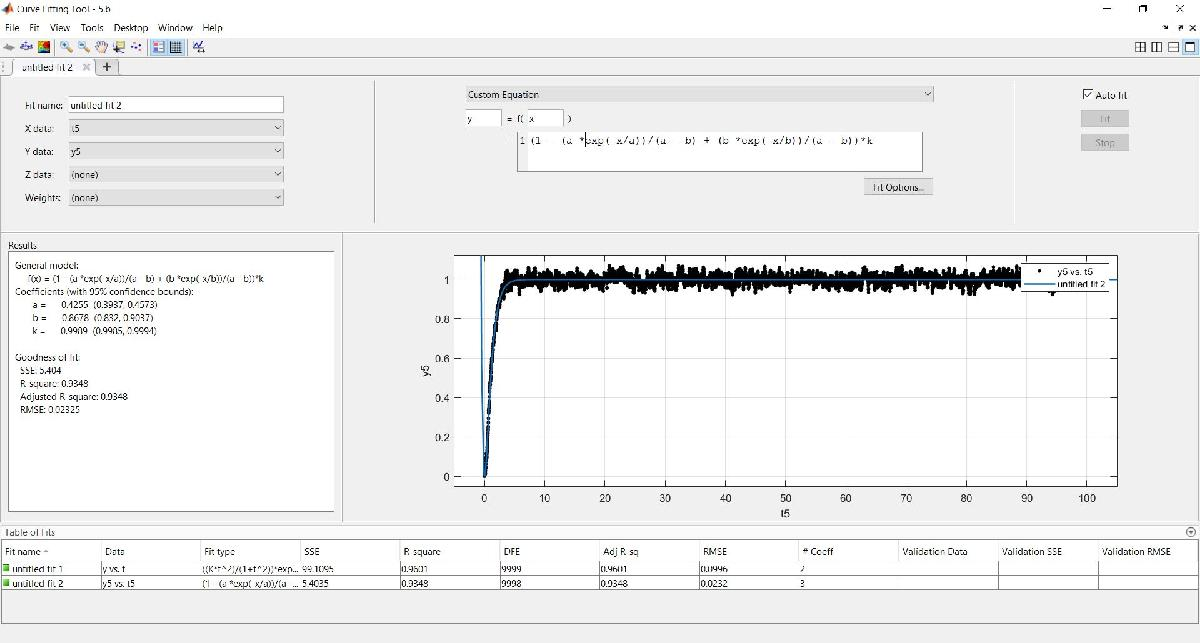

K =  0.9989 ,$\tau_1$ = 0.8678,$\tau_2$ =  0.4255

# 6 System Identification Toolbox

clc
close all
clear all

a)

t = out.tout;
x = out.x;
y = out.y;

figure
plot(t,y,t,x) 
legend("y","u")

b)

Gb = tf(tf1.Numerator , tf1.Denominator)

Gb =
 
    0.1127
  ----------
  s + 0.1128
 
Continuous-time transfer function.



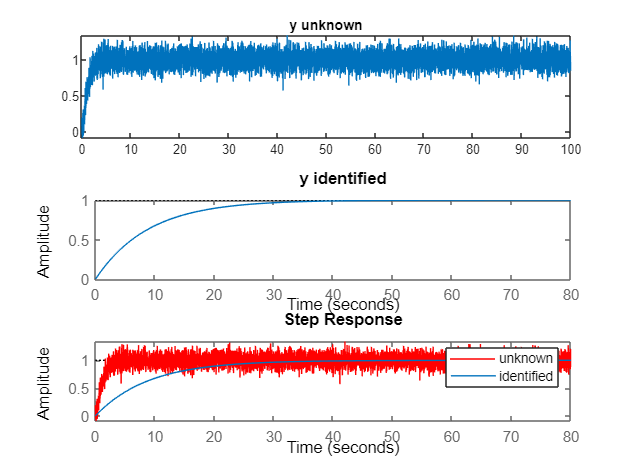

figure
subplot(3,1,1)
plot(t,y)
title("y unknown")
subplot(3,1,2)
step(Gb)
title("y identified")
subplot(3,1,3)
hold on
plot(t,y,"Color","r")
step(Gb)
legend("unknown","identified")

c)

A = 2.5

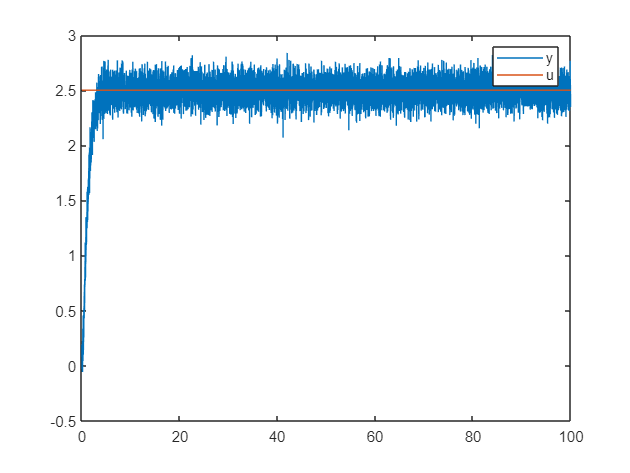

% t1 = out.tout;
% x1 = out.x;
% y1 = out.y;

figure
plot(t1,y1,t1,x1) 
legend("y","u")

Gc1 = tf(tf2.Numerator , tf2.Denominator)

Gc1 =
 
    0.1116
  ----------
  s + 0.1116
 
Continuous-time transfer function.



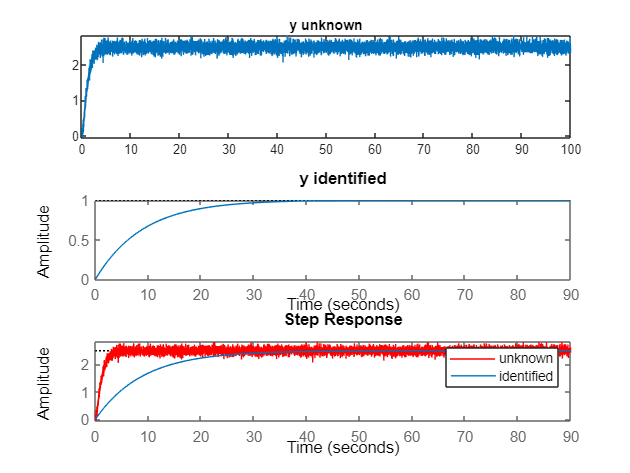

figure
subplot(3,1,1)
plot(t1,y1)
title("y unknown")
subplot(3,1,2)
step(Gc1)
title("y identified")
subplot(3,1,3)
hold on
plot(t1,y1,"Color","r")
step(2.5*Gc1)
legend("unknown","identified")

A = -2.5

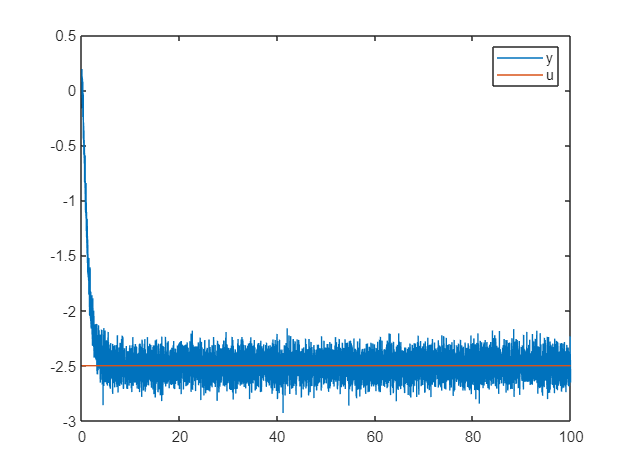

% t2 = out.tout;
% x2 = out.x;
% y2 = out.y;

figure
plot(t2,y2,t2,x2) 
legend("y","u")

Gc2 = tf(tf3.Numerator , tf3.Denominator)

Gc2 =
 
   0.1101
  --------
  s + 0.11
 
Continuous-time transfer function.



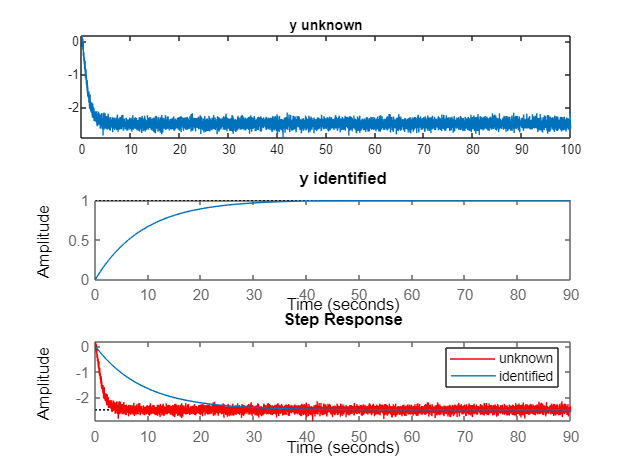

figure
subplot(3,1,1)
plot(t2,y2)
title("y unknown")
subplot(3,1,2)
step(Gc2)
title("y identified")
subplot(3,1,3)
hold on
plot(t2,y2,"Color","r")
step(-2.5*Gc2)
legend("unknown","identified")

d)

% t3 = out.tout;
% x3 = out.x;
% y3 = out.y;

figure
plot(t3,y3,t3,x3) 
legend("y","u")

Gd = tf(tf4.Numerator , tf4.Denominator)

Gd =
 
    0.1006
  -----------
  s + 0.07537
 
Continuous-time transfer function.



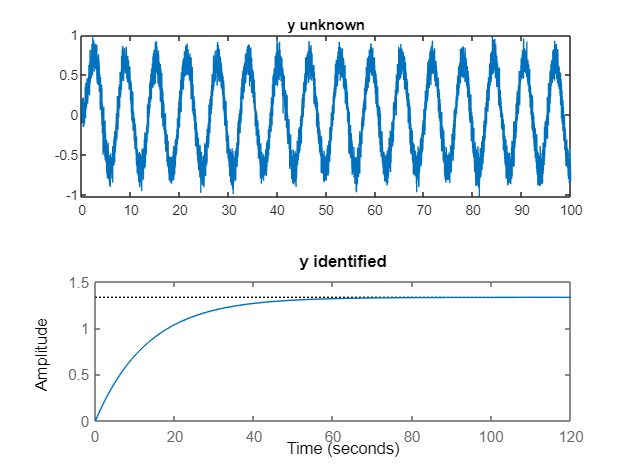

figure
subplot(2,1,1)
plot(t3,y3)
title("y unknown")
subplot(2,1,2)
step(Gd)
title("y identified")

e)

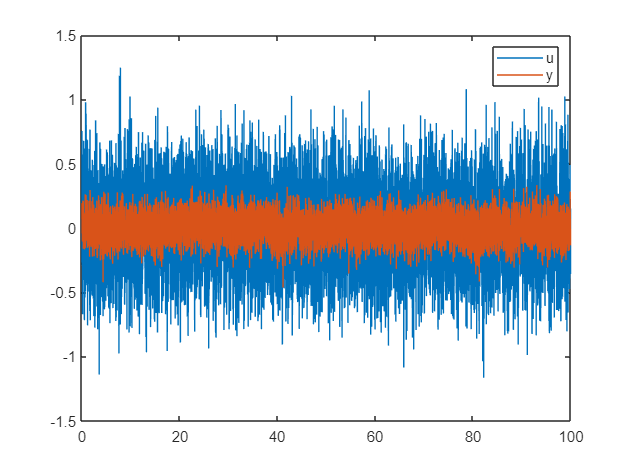

% t4 = out.tout;
% x4 = out.x;
% y4 = out.y;

figure
plot(t4,x4,t4,y4) 
legend("u","y")

Ge = tf(tf5.Numerator , tf5.Denominator)

Ge =
 
    0.08783
  -----------
  s + 0.08898
 
Continuous-time transfer function.



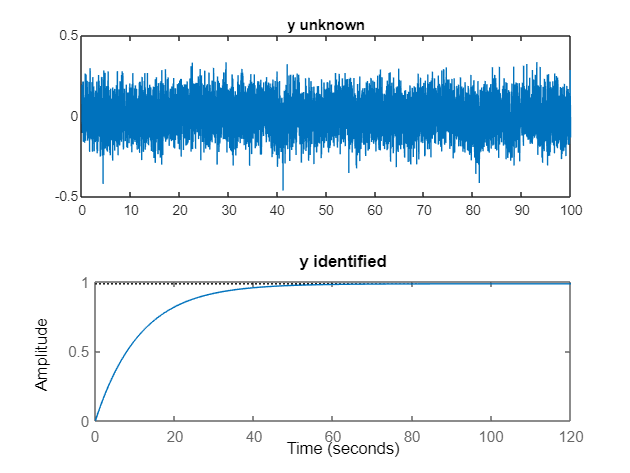


figure
subplot(2,1,1)
plot(t4,y4)
title("y unknown")
subplot(2,1,2)
step(Ge)
title("y identified")

f)

% t5 = out.tout;
% x5 = out.x;
% y5 = out.y;

figure
plot(t5,y5,t5,x5) 
legend("y","u")

Gf = tf(tf6.Numerator , tf6.Denominator)

Gf =
 
    0.1076
  ----------
  s + 0.1077
 
Continuous-time transfer function.



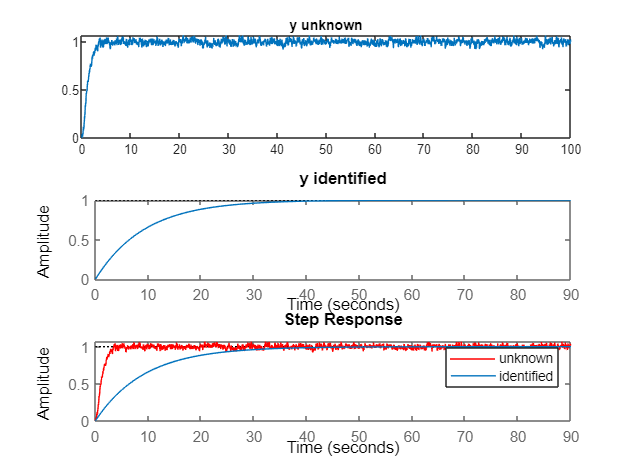

figure
subplot(3,1,1)
plot(t5,y5)
title("y unknown")
subplot(3,1,2)
step(Gf)
title("y identified")
subplot(3,1,3)
hold on
plot(t5,y5,"Color","r")
step(Gf)
legend("unknown","identified")

g)

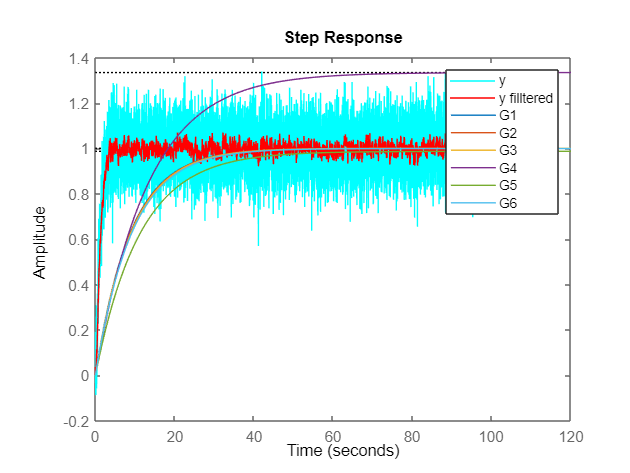

G1 = tf(tf1.Numerator , tf1.Denominator);
G2 = tf(tf2.Numerator , tf2.Denominator);
G3 = tf(tf3.Numerator , tf3.Denominator);
G4 = tf(tf4.Numerator , tf4.Denominator);
G5 = tf(tf5.Numerator , tf5.Denominator);
G6 = tf(tf6.Numerator , tf6.Denominator);

close all
hold on
plot(t,y,'c')
plot(t5,y5,'r')
step(G1)
step(G2)
step(G3)
step(G4)
step(G5)
step(G6)
legend("y","y filltered","G1","G2","G3","G4","G5","G6")

Except for the two approximations G5 and G4, the other approximations have the same and better performance.

h)

the best method is G1(part b):

figure
plot(t,y,t,x) 
legend("y","u")

Gh = tf(tf7.Numerator , tf7.Denominator)

Gh =
 
          0.08766
  ------------------------
  s^2 + 0.8126 s + 0.08775
 
Continuous-time transfer function.



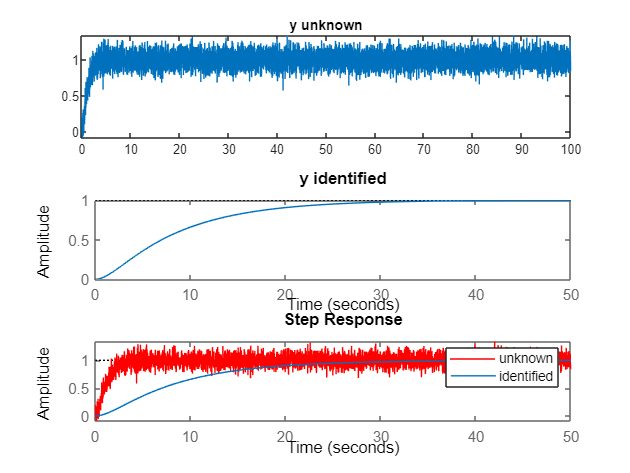

figure
subplot(3,1,1)
plot(t,y)
title("y unknown")
subplot(3,1,2)
step(Gh)
title("y identified")
subplot(3,1,3)
hold on
plot(t,y,"Color","r")
step(Gh)
legend("unknown","identified")

function [u] = Step01(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>=0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end
function [u] = Step00(C)
u = C;
s = length(C);
for i=1:s
    if C(i)>0
        u(i)=1;
    else
        u(i)=0;
    end
end    
end